Aquí se implementa el método del archivo que envié en el correo. En este lo que se pretende hacer es medir dos posibles gradientes de la siguiente posición del centro, y hacer una media entre ellas. En este código se va a comparar la media y desviación estándar que se obtendría con este método frente a la que se obtiene con el método del gradiente simple.

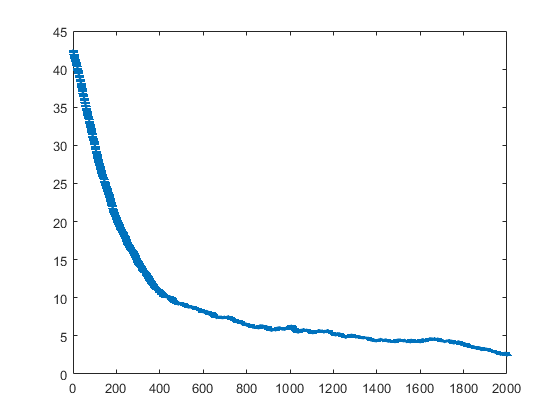

clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=4; %Número de robots
iteration=2000; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0=[30;30];
c01=[30;30];
c02=[30;30];
r0=[0 0]'; %Centro de contaminación
e=[1;0];
w0=1; %Movimiento circular de un radián por segundo

%Desviación estándar es v=2
v=2;
%Desviación en la formación de robots es delta=0.1
%delta=0.1;

colors=["ob","ok","or","oy"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
i=1;

for k=1:100
    while mod_rc>0.001
        grad_sum1=0;
        grad_sum2=0;
        if i==iteration
            break
        end
        i=i+1;

        for j=1:N
            %A este ángulo se le puede añadir movimiento rotatorio (w*t)
            phi=w0*t(i)+2*pi()*j/N;
            R=[cos(phi) -sin(phi);sin(phi) cos(phi)];
            %Posición del robot individual
            pos_rob1(:,j,i)=c01+D*R*e;
            pos_rob2(:,j,i)=c02+D*R*e;
            
            r_i1=pos_rob1(:,j,i);
            r_i2=pos_rob2(:,j,i);
            %Suma para el gradiente (esto luego se utiliza para la aprox. del
            %grad. en el centro)
            %se va a a hacer la media de las dos medidas que se obtienen
            v_i1=normrnd(0,v^2);
            grad_sum1=grad_sum1+(100*exp(-r_i1'*S*r_i1)+v_i1)*(r_i1-c01);
            v_i2=normrnd(0,v^2);
            grad_sum2=grad_sum2+(100*exp(-r_i2'*S*r_i2)+v_i2)*(r_i2-c02);
        end
        %Aproximación del gradiente en el centro
        grad_centr1=2/(N*D^2)*grad_sum1;
        grad_centr2=2/(N*D^2)*grad_sum2;
    
        grad_centr=1/2*(grad_centr1+grad_centr2);
        step_size=0.1;
        c(:,i)=c0+step_size*grad_centr;
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
        c0=c(:,i);
    
        c1(:,i)=c01+step_size*grad_centr1;
        c01=c1(:,i);
    
        c2(:,i)=c02+step_size*grad_centr2;
        c02=c2(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
        mod_r_c(i)=norm(c0-r0);
        mod_r_c1(i)=norm(c01-r0);
        mod_r_c2(i)=norm(c02-r0);

        mod_rc=mod_r_c(i);
    end
    mod_rc_sim(:,k)=mod_r_c;
    mod_rc_sim1(:,k)=mod_r_c1;
    mod_rc_sim2(:,k)=mod_r_c2;
end

%Representación de la media y la desviación estándar
for h=1:iteration
    media(h)=mean(mod_rc_sim(h,:));
    desv_std(h)=std(mod_rc_sim(h,:));
    media1(h)=mean(mod_rc_sim1(h,:));
    desv_std1(h)=std(mod_rc_sim1(h,:));
    media2(h)=mean(mod_rc_sim2(h,:));
    desv_std2(h)=std(mod_rc_sim2(h,:));
end
errorbar(1:iteration,media,desv_std,'.')
hold off

media_gradiente=media(iteration)

media_gradiente = 2.4424

desv_est=desv_std(iteration)

desv_est = 5.3559e-15

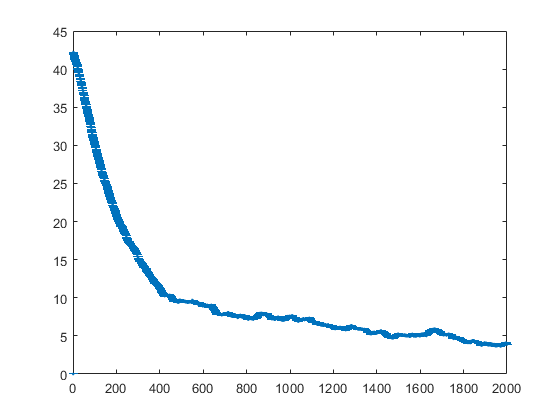

errorbar(1:iteration,media1,desv_std1,'.')
hold off

media1=media1(iteration)

media1 = 3.8693

desv_est1=desv_std1(iteration)

desv_est1 = 3.5706e-15

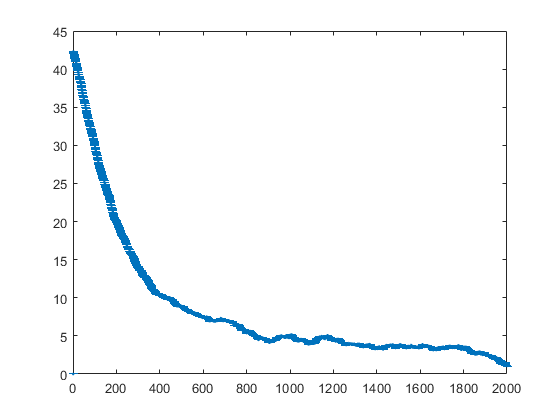

errorbar(1:iteration,media2,desv_std2,'.')
hold off

media2=media2(iteration)

media2 = 1.0470

desv_est2=desv_std2(iteration)

desv_est2 = 8.9265e-16

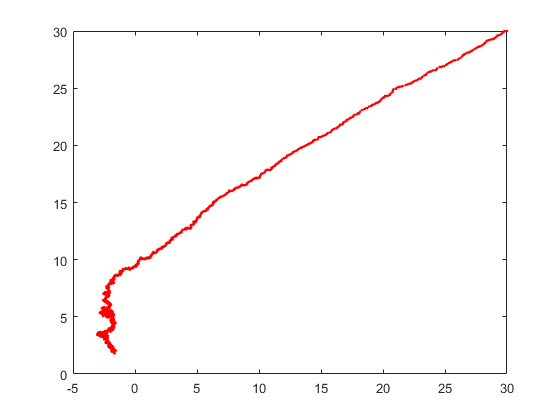

%Representación del centro de la formación
plot(c(1,:),c(2,:),'.r')
hold off

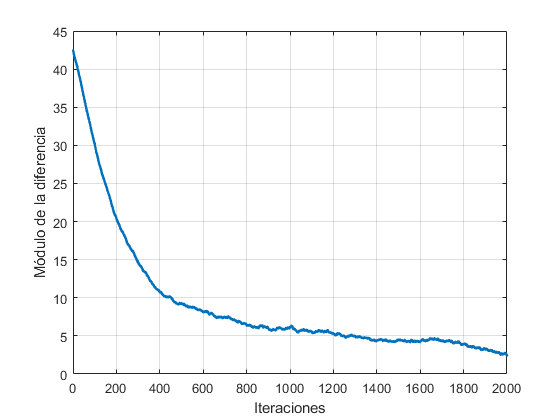

plot(1:length(mod_r_c),mod_r_c,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on
hold off

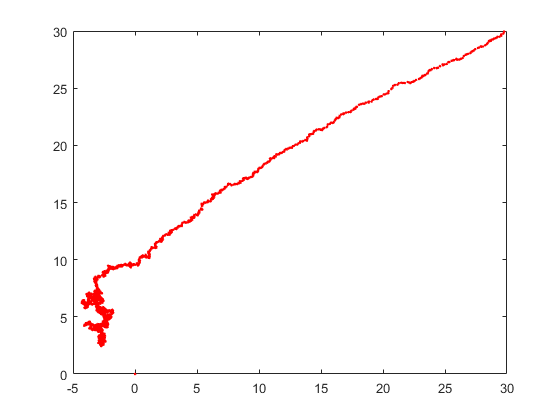

plot(c1(1,:),c1(2,:),'.r')
hold off

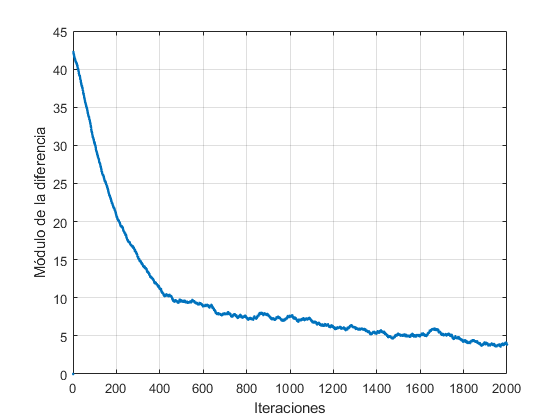

plot(1:length(mod_r_c1),mod_r_c1,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on
hold off

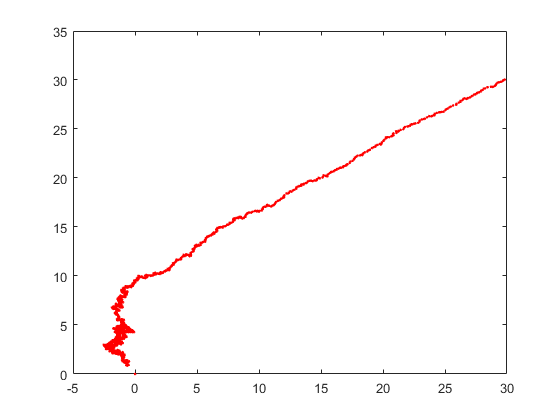

plot(c2(1,:),c2(2,:),'.r')
hold off

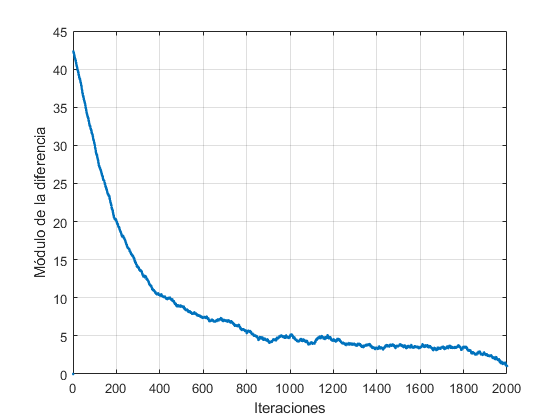

plot(1:length(mod_r_c2),mod_r_c2,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on
hold off

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 2.4424

c0

c0 =    -1.6286
    1.8202
